# Yaw Thrust from Pitch - Parameter Estimation

There is a reaction torque acting on the yaw axis from the pitch rotor. This lab shows how to find the thrust gain parameter that captures this effect. 

## Concept Review

In the 2 DOF configuration, the motion of the yaw is affected by both rotors. The yaw/rear rotor applies a direct thrust about the yaw axis but the pitch/front rotor generates a torque on the yaw axis as well. This can be respresented by the following equation of motion (EOM):

The Aero 2 yaw axis model can be represented by the equation of motion 


$$J_y \ddot{\psi} + D_y \dot{\psi} = K_{yy}D_tV_y + K_{yp}D_tV_p$$


where $\psi$ is the yaw angle, $J_y$ is the equivalent moment of inertia acting about the yaw axis, $D_y$ is the viscous damping, $K_{yy}$ is the yaw thrust force gain from the yaw rotor, $K_{yp}$ is the thurst force gain acting on the yaw axis from the pitch rotor, $D_t$ is the distance from the pivot point to the propeller, and $V_y$ is the voltage applied to the rear/yaw rotor motor. 

The pitch thrust, inertia, damping, and stiffness were identified in the 2* DOF Parameter Estimation: Yaw *lab. Because we are only applying a voltage to the pitch/front rotor, $V_y=0$, and the pitch-axis is locked the EOM becomes


$$J_y\ddot{\psi} + D_y \dot{\psi} = K_{yp} D_t V_p$$


Solving for the thrust gain parameter 


$$K_{yp} =\frac{J_y \ddot{\psi} + D_y \psi}{D_tV_p}$$


We can find the thrust gain from the measure yaw rate and derived acceleration 

## Lab Procedure

Apply a step to front/pitch motor and measure yaw response. Load existing data or run the Simuilnk model in QUARC to take new measurements.

### Setup

- Make sure the Aero 2 has been tested as instructed in the Quick Start Guide. 

- Launch MATLAB and browse to the working directory that includes the Simulink models for this lab.

- Configure the Aero 2 in the 2 DOF Helicopter configuration: 

- **Unlock** the pitch axis and **lock **the yaw axis.

- Rear rotor 1 is **vertical **and front rotor 0 is **horizontal**.

- Mount weight on each rotor.

- Connect the USB cable to your PC/laptop.

- Connect the power and turn the power switch ON. The Aero base LED should be red.

### Lab 1: Get Open-Loop Response

The open-loop response can be obtained by running the `q_aero2_yaw_from_pitch_step `Simulink model shown in Figure 1 with QUARC. 

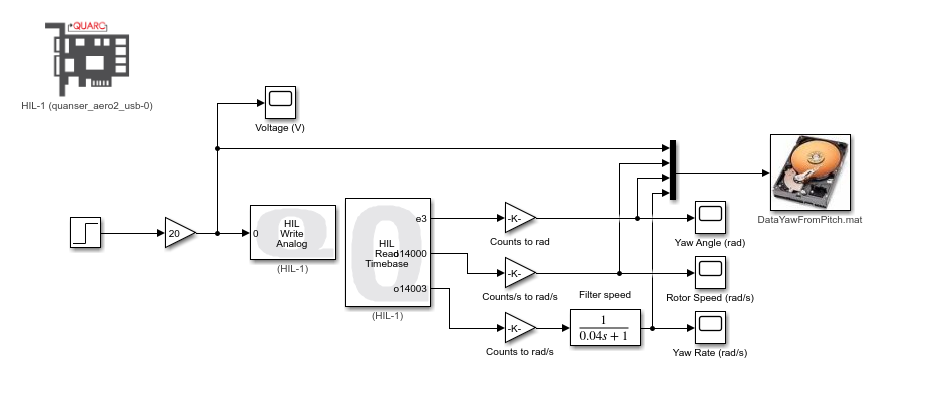

Figure 1 - Simulink model used with QUARC to apply a voltage to the front rotor and measure the yaw rate and angle.

The Simulink model uses the `HIL Write Analog `and `HIL Read Timebase `blocks from the *QUARC Targets *library to apply a voltage to the front pitch rotor and measure the corresponding pitch angle response. The response is saved into a MATLAB *.mat files using the `To Host File `block. This can then be used to plot the results and perform the parameter estimation analysis. 

Build and run the following Simulink model in QUARC by clicking on the *Monitor & Tune* button.

% Load Simulink model
open("q_aero2_yaw_from_pitch_step.slx");

Figure 2 shows the yaw rate response and applied voltage in the scopes. 

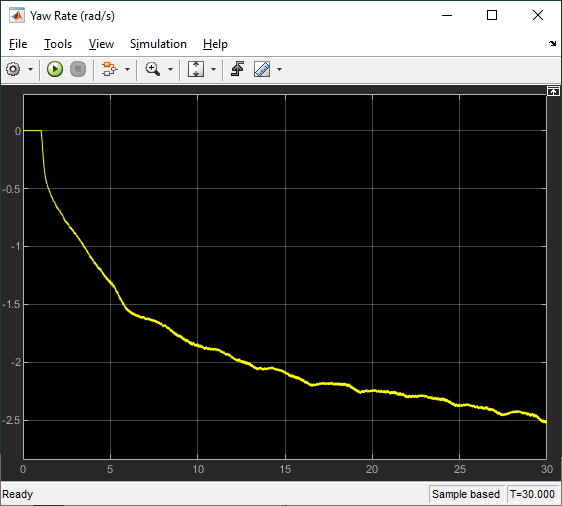 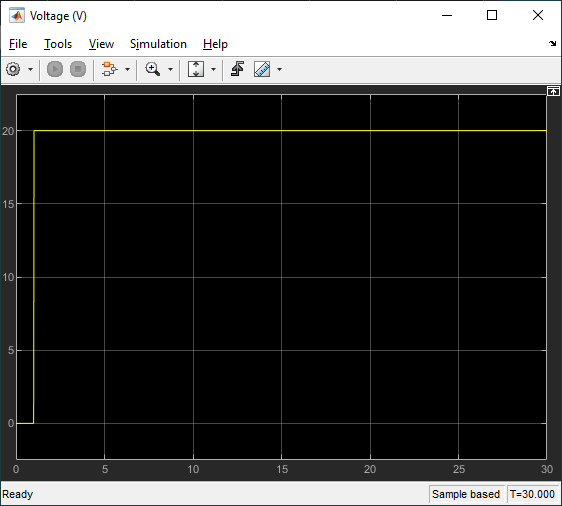

Figure 2 - Yaw angle rate response from applying a step to the front pitch rotor. 

Plot measured response

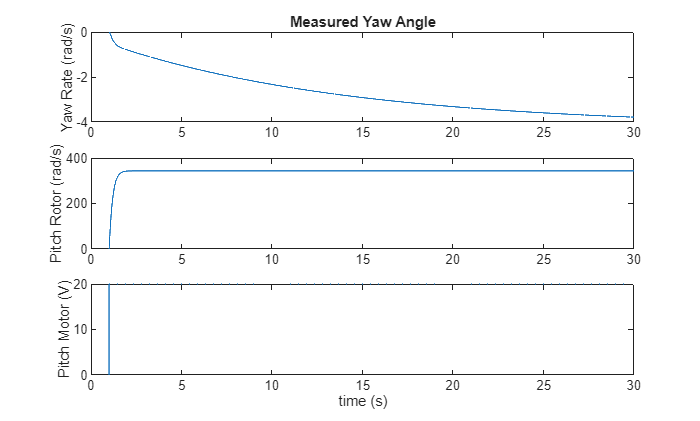

% Load measured data from past run
load('DataYawFromPitch.mat');
% store in variables
t = YawFromPitch(1,:); % time (s)
Vp = YawFromPitch(2,:); % pitch/front motor voltage (V)
wm_p= YawFromPitch(3,:); % pitch/front rotor speed (rad/s)
psi = YawFromPitch(4,:); % yaw angle (rad)
psi_dot = YawFromPitch(5,:); % yaw angular rate (rad/s)
%
subplot(3,1,1);
plot(t,psi_dot);
title('Measured Yaw Angle');
ylabel('Yaw Rate (rad/s)');
subplot(3,1,2);
plot(t,wm_p);
ylabel('Pitch Rotor (rad/s)');
subplot(3,1,3);
plot(t,Vp);
ylabel('Pitch Motor (V)');
xlabel('time (s)');

### Lab 2: Find Thrust Gain

Load the AERO 2 Parameters

aero2_parameters;

Load stiffness, damping, and thrust parameter values that you found in the parameter estimation lab.

% Thrust (N-m/V)
Kyy = 0.00614;
% Damping (N-m/V)
Dy = 0.00214;

Find the yaw from pitch thrust force gain.

% Sampling interval of controller (s)
h = 0.002;
% Yaw acceleration from measured rate (rad/s^2)
psi_ddot = diff(psi_dot)/h;
% size of acceleration response
iif = length(psi_ddot);
% Thrust gain (N/V)
Kyp = ( Jy*psi_ddot + Dy*psi_dot(1:iif) ) / ( Dt*Vp(1:iif) )

Kyp = -0.0027

The measured cross-thrust acting on the yaw-axis from the pitch/front rotor is

$K_{yp}=-0.00185$ N/m